Loading data

clear, clc
data = csvread("data_steering.csv",1,0);

time = data(:,1)/1000;
voltage = data(:,2);
position = data(:,3);
Ts = mean(diff(time))

Ts = 0.0100

Filtering speed mesured

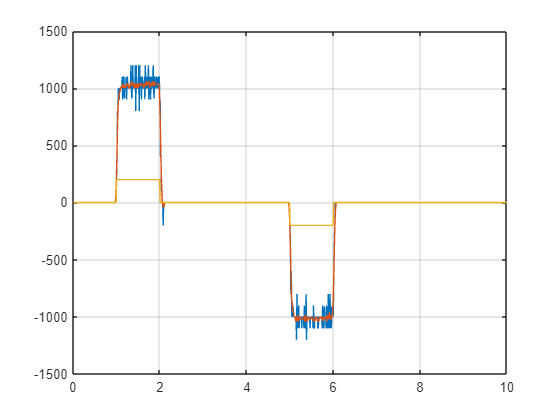

speed_raw = diff(position)./diff(time);

speed = movmean(speed_raw,5);

hold off
plot(time(1:end-1), speed_raw,time(1:end-1), speed)
hold on 
plot(time, 40*voltage)

grid on
hold off

Model estimation

DCData = iddata(speed,voltage(1:end-1),Ts);
get(DCData);

ans = struct with fields:
              Domain: 'Time'
                Name: ''
          OutputData: [995×1 double]
                   y: 'Same as OutputData'
          OutputName: {'y1'}
          OutputUnit: {''}
           InputData: [995×1 double]
                   u: 'Same as InputData'
           InputName: {'u1'}
           InputUnit: {''}
              Period: Inf
         InterSample: 'zoh'
                  Ts: 0.0100
              Tstart: 0.0100
    SamplingInstants: [995×1 double]
            TimeUnit: 'seconds'
      ExperimentName: 'Exp1'
               Notes: {}
            UserData: []


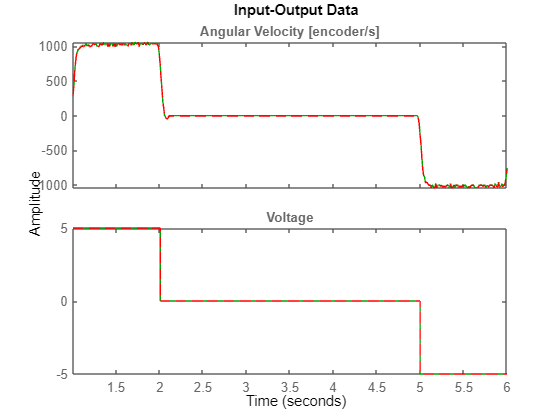

DCData.InputName = 'Voltage';
DCData.OutputName = 'Angular Velocity [encoder/s]';
DCData.TimeUnit = 'seconds';
DCData.InputUnit = 'V';
DCData.OutputUnit = 'encoder/s';
% Select time window for data used for estimation and model parameter validation
twin_init=1;
twin_fin=6;
pas=time(length(speed))/length(speed);
NEstimStart=round(twin_init/pas);
NEstimEnd=round(twin_fin/pas);
NValStart=1;
NValEnd=length(speed);
% select data for identif
DCDataIdent = DCData(NEstimStart:NEstimEnd);
% plot raw data for identif
figure(2)
plot(DCDataIdent,'-g');
hold on
% plot data after having removed the trend (mean)
DCDataIdent = detrend(DCDataIdent);
plot(DCDataIdent,'--r');
hold off


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Estimate models parameters  %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% transfert function parameter estimation
TFModel = tfest(DCDataIdent, 1, 0, 0)       % first order + integrator

TFModel =
  From input "Voltage" to output "Angular Velocity [encoder/s]":
    9925
  ---------
  s + 48.96
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                 
Estimated using TFEST on time domain data "DCDataIdent".
Fit to estimation data: 95.32%                          
FPE: 897.8, MSE: 887                                    
 
Model Properties


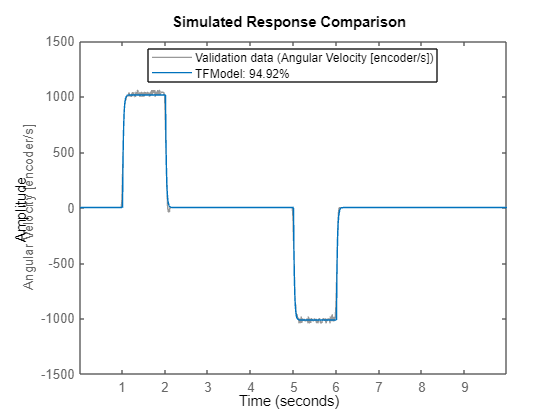

%Validating the Estimated Model to Experimental Output
DCDataVal = DCData(NValStart:NValEnd);      % select an independent data set for validation
DCDataVal = detrend(DCDataVal);             % preprocess the validation data
figure(3)
set(gcf,'DefaultLegendLocation','best')
compare(DCDataVal,TFModel);

PID Tuning for Control in Position [pos in number of encoders ]

K = TFModel.Numerator/TFModel.Denominator(2)

K = 202.7269

tau = 1/TFModel.Denominator(2)

tau = 0.0204


sys = tf([K 0],[tau 1 0])

sys =
 
      202.7 s
  ---------------
  0.02042 s^2 + s
 
Continuous-time transfer function.



sys_d = c2d(sys, Ts)% z =0.7, tr = 0.1s

sys_d =
 
    78.72
  ----------
  z - 0.6117
 
Sample time: 0.010039 seconds
Discrete-time transfer function.




pidTuner(sys_d)
Kp = 0.001311

Kp = 0.0013

Ki = 0.1056

Ki = 0.1056

After the experiment, with find this coeficient to covert the encoder data to rad

D = [deg2rad(37)/1250, deg2rad(28)/1000, deg2rad(22.5)/750, deg2rad(16)/500, deg2rad(7.5)/250]

df = 1.0e-03 *

    0.5166    0.4887    0.5236    0.5585    0.5236


mean(D)

ans = 5.2220e-04

std(D)

ans = 2.4879e-05

std(D)/mean(D)

ans = 0.0476

coef = 5.2e-4

coef = 5.2000e-04

PID Tuning for Control in Speed [spd in rad/s]

K = coef*TFModel.Numerator/TFModel.Denominator(2)

K = 0.1054

tau = 1/TFModel.Denominator(2)

tau = 0.0204


sys = tf([K],[tau 1])

sys =
 
     0.1054
  -------------
  0.02042 s + 1
 
Continuous-time transfer function.



sys_d = c2d(sys, Ts)

sys_d =
 
   0.04093
  ----------
  z - 0.6117
 
Sample time: 0.010039 seconds
Discrete-time transfer function.




pidTuner(sys_d)% z =0.7, tr = 0.04s
Kp	= 11.4217

Kp = 11.4217

Ki	= 515.9935

Ki = 515.9935

Finding Luenbergue coeficients for speed estimation

%x = v theta d
%y = theta
Ao = [-1/tau, 0 K/tau; 1 0 0; 0 0 0]

Ao =   -48.9597         0    5.1612
    1.0000         0         0
         0         0         0


Bo = [K/tau; 0; 0]

Bo =     5.1612
         0
         0


Co = [0 1 0]

Co =      0     1     0



sys = ss(Ao,Bo,Co,0)

sys =
 
  A = 
           x1      x2      x3
   x1  -48.96       0   5.161
   x2       1       0       0
   x3       0       0       0
 
  B = 
          u1
   x1  5.161
   x2      0
   x3      0
 
  C = 
       x1  x2  x3
   y1   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



rank(obsv(sys))

ans = 3


Ko = place(Ao', Co', [-2/tau, -3/tau, -4/tau])'

Ko = 1.0e+05 *

    0.4315
    0.0039
    5.4573



sys_d = c2d(sys,Ts, 'zoh')

sys_d =
 
  A = 
              x1         x2         x3
   x1     0.6117          0    0.04093
   x2   0.007931          1  0.0002222
   x3          0          0          1
 
  B = 
              u1
   x1    0.04093
   x2  0.0002222
   x3          0
 
  C = 
       x1  x2  x3
   y1   0   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.010039 seconds
Discrete-time state-space model.

